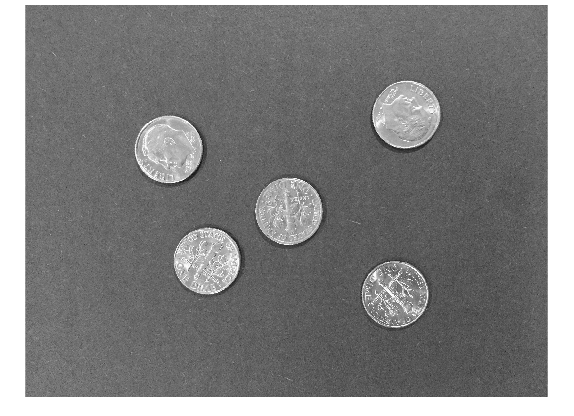

img = imread("coins-3.jpg");
imshow(img)

bw = imbinarize(img);
ctr = sum(bw(:) == 1);
ctr

ctr = 594617

img = imread("coins-3.jpg");
imshow(img)

bw = imbinarize(img);
ctr2 = sum(bw(:) == 0);
ctr2

ctr2 = 7395655

img = imread("coins-3.jpg");
imshow(img)

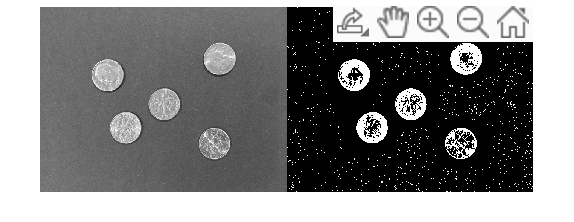

bw2 = imbinarize(img,"adaptive");
montage({img, bw2})

[~,effectivenessMetric1] = graythresh(img)

effectivenessMetric1 = 0.6967

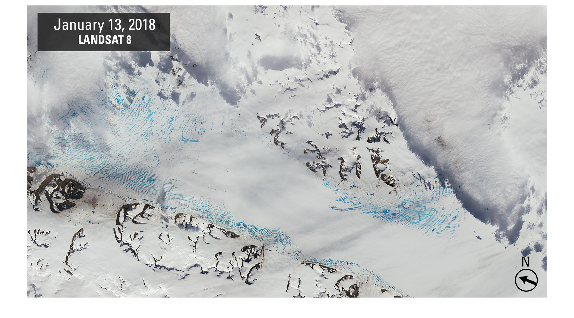

img1 = imread("Data/George VI Ice Shelf/1_SnowPoolsBefore_20180113_md-2048px.jpg");
imshow(img1)


img1 = imread("1_SnowPoolsBefore_20180113_md-2048px.jpg");
img2 = imread("2_SnowPoolsAfter_20200119_md-2048px.jpg");
[BW1, maskedImg1] = createMaskforglacier(img1);
[BW2, maskedImg2] = createMaskforglacier(img2);
figure
montage({img1, maskedImg1})
figure
montage({img2, maskedImg2})